# Projeto 

## META 1

## 1

% Criar tabela
path = "data/36"

path = "data/36"

files = dir(path)

files = 502×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filteredFiles = files([files.isdir] == 0);
tab = struct2table(filteredFiles)

tab = 500×6 table
         name                                      folder                                           date              bytes    isdir     datenum  
    _______________    _______________________________________________________________    ________________________    _____    _____    __________

    {'0_36_0.wav' }    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'28-Dez-2020 07:38:02'}    77318    false    7.3815e+05
    {'0_36_1.wav' }    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'28-Dez-2020 07:38:02'}    72478    false    7.3815e+05
    {'0_36_10.wav'}    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'28-Dez-2020 07:38:02'}    87908    false    7.3815e+05
    {'0_36_11.wav'}    {'/Users/franciscos

% Número de arquivos
nFiles = height(tab);

% Pré-alocar vetores para os dados que serão extraídos
% Lembre que no nome: o primeiro número é o dígito, 
% o segundo é o participante e o terceiro é o número de repetições.
digits = zeros(nFiles, 1);
participants = zeros(nFiles, 1);
repetitions = zeros(nFiles, 1);

% Processar cada nome de ficheiro para extrair os números
for i = 1:nFiles
    % Obter o nome do ficheiro (com extensão)
    filename = tab.name{i};  % Se estiver armazenado como cell array de char
    % Remover a extensão (ex.: '.wav')
    [~, nameNoExt, ~] = fileparts(filename);
    % Separar os componentes usando o underline como delimitador
    parts = split(nameNoExt, '_');
    
    if numel(parts) >= 3
        % Converter os componentes para número
        digits(i) = str2double(parts{1});
        participants(i) = str2double(parts{2});
        repetitions(i) = str2double(parts{3});
    else
        warning('Formato de nome inesperado: %s', filename);
        digits(i) = NaN;
        participants(i) = NaN;
        repetitions(i) = NaN;
    end
end

% Criar a nova tabela com as colunas desejadas:
% - AudioDirectory: diretório de áudio (coluna 'folder')
% - FileName: nome do ficheiro (com extensão, coluna 'name')
% - Participant: segundo número do nome
% - Digit: primeiro número do nome
% - Repetitions: terceiro número do nome
newTable = table(tab.folder, tab.name, participants, digits, repetitions, ...
    'VariableNames', {'AudioDirectory', 'FileName', 'Participant', 'Digit', 'Repetitions'})

newTable = 500×5 table
                            AudioDirectory                                FileName        Participant    Digit    Repetitions
    _______________________________________________________________    _______________    ___________    _____    ___________

    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_0.wav' }        36           0           0     
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_1.wav' }        36           0           1     
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_10.wav'}        36           0          10     
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_11.wav'}        36           0          11     
    {'/Users/franciscosantos/Documents/GitHub/Proj

## 2

arquivos = dir(fullfile(path, "*.wav"));
nomes = {arquivos.name}';  % Lista de nomes dos arquivos
taxasAmostragem = zeros(length(arquivos), 1);  % Vetor para taxas de amostragem
sinais = cell(length(arquivos), 1);  % Célula para armazenar os sinais

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name); % Caminho completo
    [sinal, fs] = audioread(caminhoArquivo); % Ler áudio
    taxasAmostragem(i) = fs;  % Armazena a taxa de amostragem
    sinais{i} = sinal;  % Armazena o sinal de áudio
end

% Criar tabela com os dados
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38637×1 double}
    {'0_36_1.wav' }         48000         {36217×1 double}
    {'0_36_10.wav'}         48000         {43932×1 double}
    {'0_36_11.wav'}         48000         {35604×1 double}
    {'0_36_12.wav'}         48000         {34260×1 double}
    {'0_36_13.wav'}         48000         {35326×1 double}
    {'0_36_14.wav'}         48000         {40242×1 double}
    {'0_36_15.wav'}         48000         {38791×1 double}
    {'0_36_16.wav'}         48000         {41981×1 double}
    {'0_36_17.wav'}         48000         {40212×1 double}
    {'0_36_18.wav'}         48000         {39723×1 double}
    {'0_36_19.wav'}         48000         {39483×1 double}
    {'0_36_2.wav' }         48000         {42

## 3

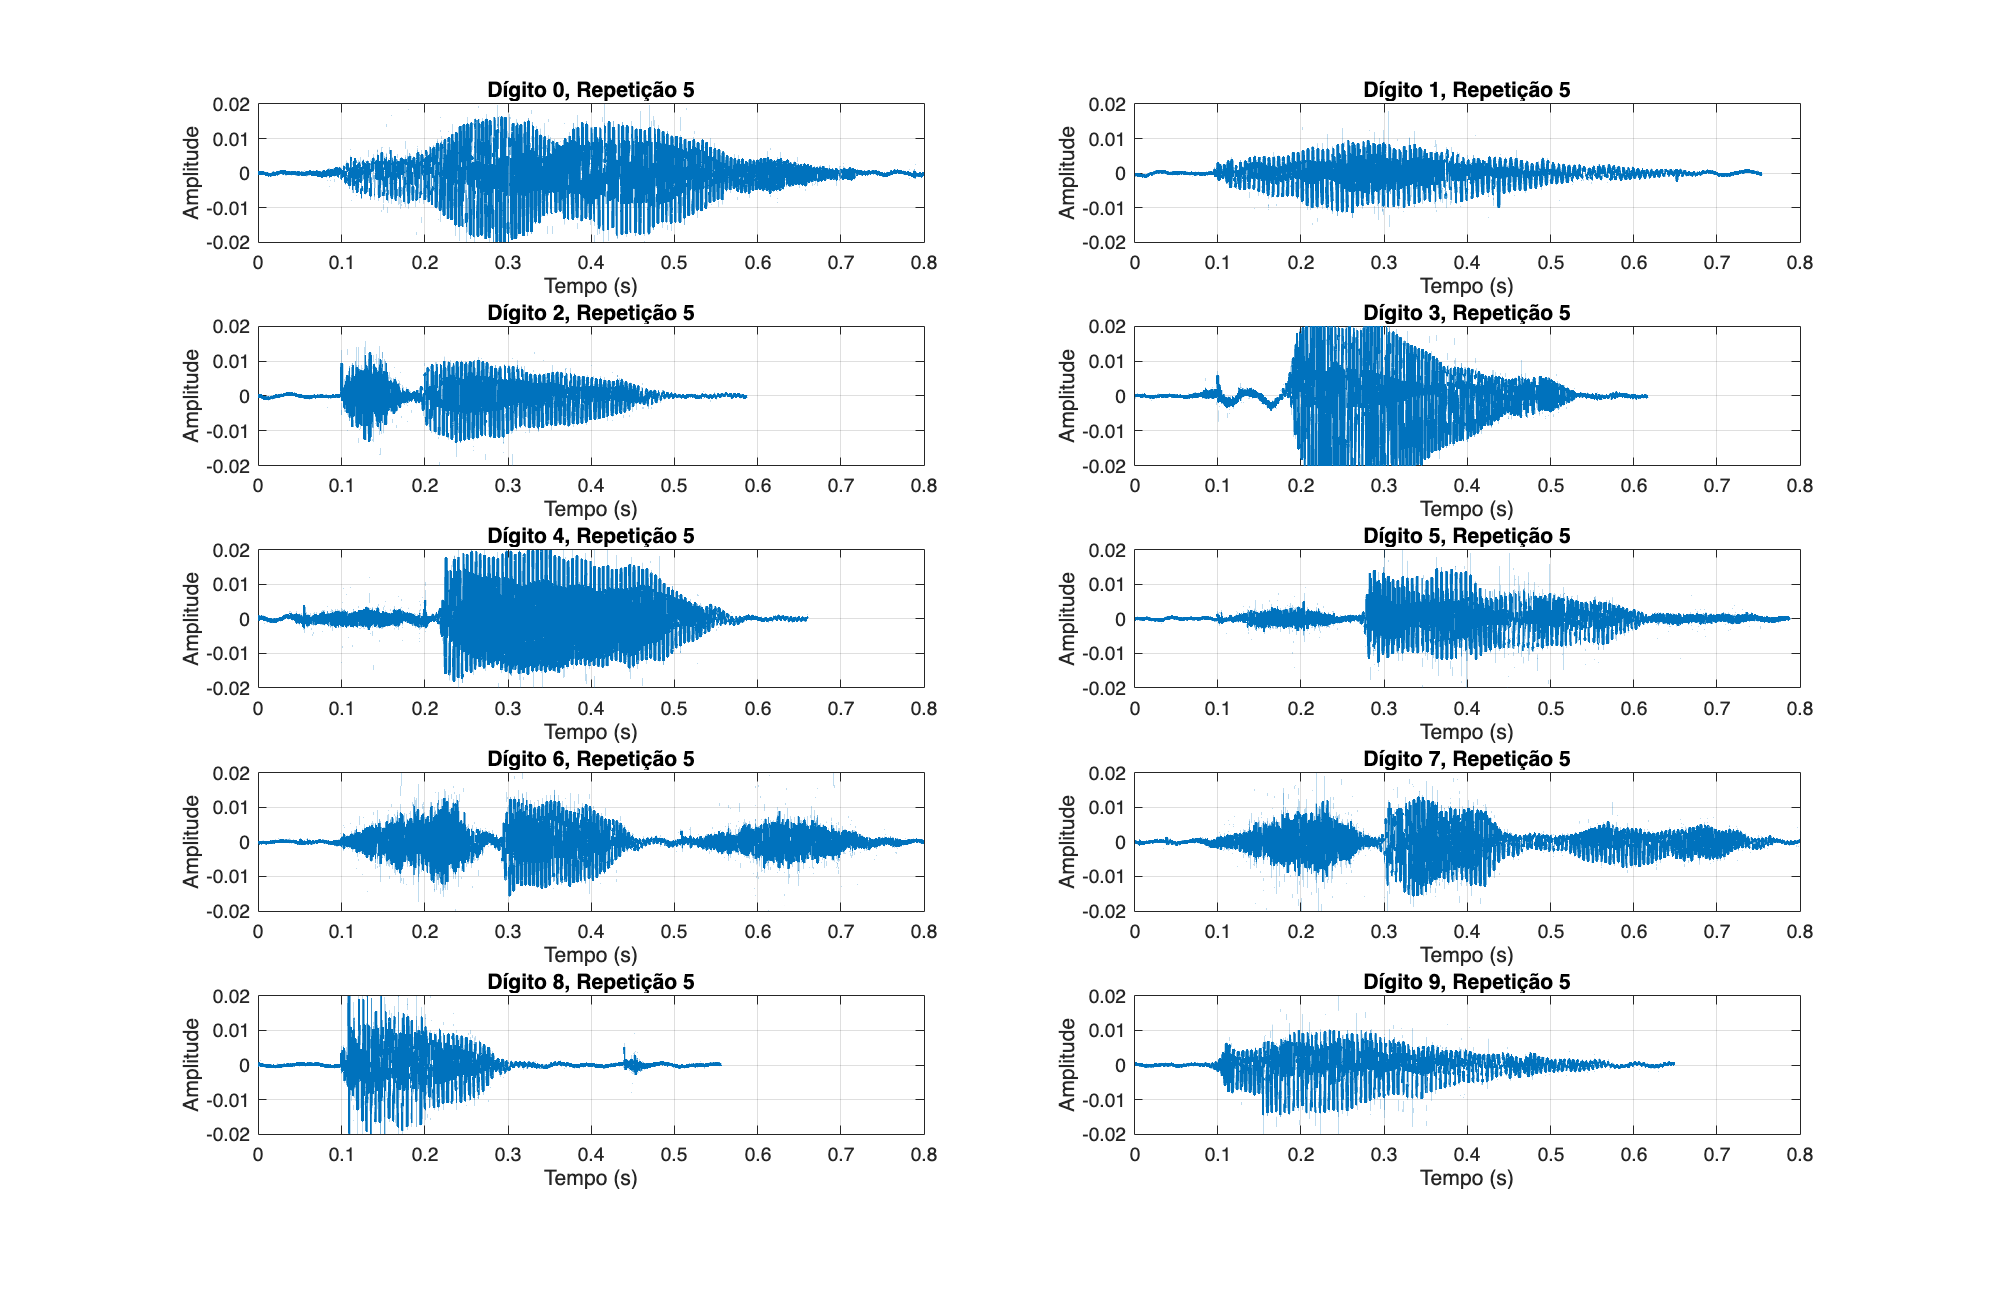

% Extração dos dígitos e repetições (descomente se ainda não executou)
nFiles = height(tabArquivos);
digitos = zeros(nFiles,1);
repeticoes = zeros(nFiles,1);
for i = 1:nFiles
   [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
   partes = split(nomeSemExt, '_');
   digitos(i) = str2double(partes{1});       % Primeiro número = dígito
   repeticoes(i) = str2double(partes{3});      % Terceiro número = repetição
end
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtrar apenas a repetição 5
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);

% Obter os dígitos disponíveis nessa repetição
uniqueDigitos = unique(T_filtro.Digito);
numDigitos = numel(uniqueDigitos);

if numDigitos < 1
    error('Nenhum dígito disponível na repetição %d.', repEscolhida);
end

% Configuração: dois gráficos por linha
nCols = 2;
nRows = ceil(numDigitos / nCols);

% Criar figura mais alta (80% da altura da tela, por exemplo)
figure('Name', sprintf('Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

% Loop para plotar cada dígito
for i = 1:numDigitos
    currentDigit = uniqueDigitos(i);
    
    % Seleciona, para o dígito atual, o primeiro arquivo (pode ser adaptado)
    T_current = T_filtro(T_filtro.Digito == currentDigit, :);
    
    sinal = T_current.Sinal{1};
    fs = T_current.Taxa_Amostragem(1);
    
    % Vetor de tempo para o sinal
    t = (0:length(sinal)-1) / fs;
    
    % Criação do subplot
    subplot(nRows, nCols, i)
    plot(t, sinal, 'LineWidth', 2)  % Aumentando a espessura da linha
    title(sprintf('Dígito %d, Repetição %d', currentDigit, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    set(gca, 'FontSize', 12)  % Aumenta o tamanho da fonte do eixo

    % Ajuste de limites (se desejar deixá-los fixos)
    xlim([0 0.8])
    ylim([-0.02 0.02])
    
    % Se preferir autoajuste no eixo Y, comente a linha acima e use:
    % ylim('auto')
    % ou axis tight (que ajusta todos os eixos):
    % axis tight

    grid on
end

## 4

arquivos = dir(fullfile(path, "*.wav"));
nomes = {arquivos.name}';  % Lista de nomes dos arquivos
taxasAmostragem = zeros(length(arquivos), 1);  % Vetor para taxas de amostragem
sinais = cell(length(arquivos), 1);  % Célula para armazenar os sinais pré-processados

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name); % Caminho completo
    [sinal, fs] = audioread(caminhoArquivo); % Ler áudio
    
    %% 1. Remover o "silêncio" inicial
    % Para isto, usamos um threshold para detectar o início efetivo da fala.
    % O valor do threshold pode ser ajustado conforme as características dos sinais.
    threshold = 0.02;  % Valor de threshold (ajuste conforme necessário)
    idx = find(abs(sinal) > threshold, 1, 'first');
    if ~isempty(idx)
        sinal = sinal(idx:end);  % Remove os samples anteriores ao início do sinal ativo
    end
    
    %% 2. Normalizar a amplitude com base na amplitude máxima e mínima
    % Isso garante que o sinal fique no intervalo [-1, 1], minimizando efeitos da distância ao microfone.
    if max(sinal) ~= min(sinal)
        sinal = 2 * (sinal - min(sinal)) / (max(sinal)-min(sinal)) - 1;
    end
    
    %% 3. Ajustar a duração total do sinal
    % Define-se uma duração alvo (em segundos) para todos os sinais.
    % Se o sinal for menor, acrescenta-se silêncio (zeros) no fim; se for maior, corta-se o excesso.
    duracao_alvo = 0.8;  % duração desejada em segundos (pode ser ajustada)
    num_amostras_alvo = round(duracao_alvo * fs);
    
    if length(sinal) < num_amostras_alvo
        % Adiciona silêncio ao fim para completar a duração
        sinal = [sinal; zeros(num_amostras_alvo - length(sinal), 1)];
    elseif length(sinal) > num_amostras_alvo
        % Corta o sinal para que tenha a duração desejada
        sinal = sinal(1:num_amostras_alvo);
    end
    
    % Armazena a taxa de amostragem e o sinal pré-processado
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

% Criar tabela com os dados pré-processados
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38400×1 double}
    {'0_36_1.wav' }         48000         {38400×1 double}
    {'0_36_10.wav'}         48000         {38400×1 double}
    {'0_36_11.wav'}         48000         {38400×1 double}
    {'0_36_12.wav'}         48000         {38400×1 double}
    {'0_36_13.wav'}         48000         {38400×1 double}
    {'0_36_14.wav'}         48000         {38400×1 double}
    {'0_36_15.wav'}         48000         {38400×1 double}
    {'0_36_16.wav'}         48000         {38400×1 double}
    {'0_36_17.wav'}         48000         {38400×1 double}
    {'0_36_18.wav'}         48000         {38400×1 double}
    {'0_36_19.wav'}         48000         {38400×1 double}
    {'0_36_2.wav' }         48000         {38

## 5

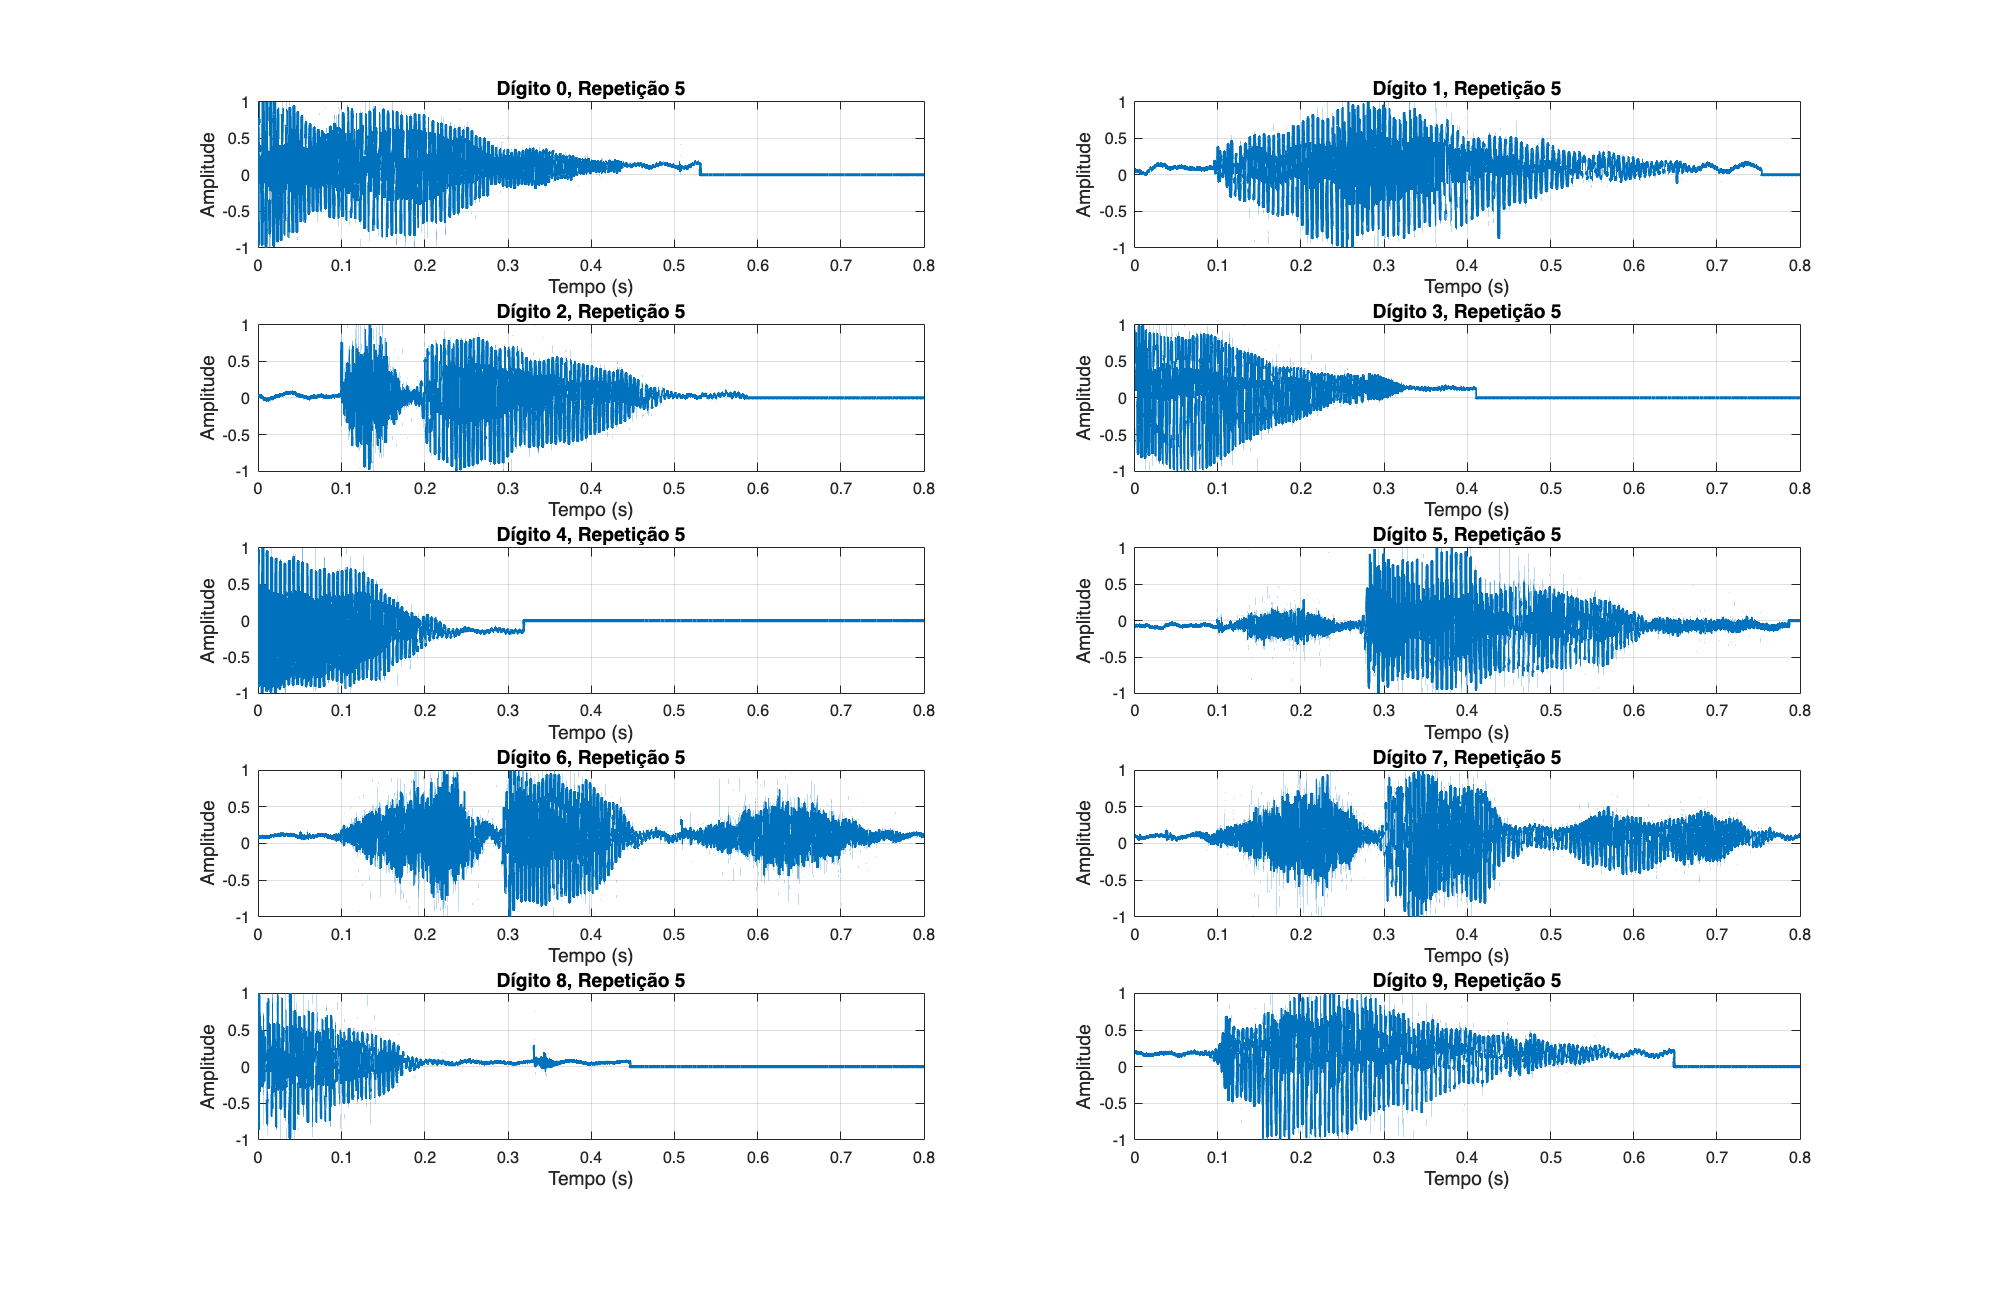

%% Supondo que a tabela "tabArquivos" já foi criada após o pré-processamento
% tabArquivos possui as colunas: Nome_Arquivo, Taxa_Amostragem, Sinal

%% 1. Extrair dígito e repetição a partir do nome dos ficheiros
nFiles = height(tabArquivos);
digitos = zeros(nFiles,1);
repeticoes = zeros(nFiles,1);

for i = 1:nFiles
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    
    if numel(partes) >= 3
        digitos(i) = str2double(partes{1});       % Primeiro número = dígito
        repeticoes(i) = str2double(partes{3});      % Terceiro número = repetição
    else
        warning('Formato de nome inesperado: %s', tabArquivos.Nome_Arquivo{i});
        digitos(i) = NaN;
        repeticoes(i) = NaN;
    end
end

% Acrescenta as novas colunas na tabela
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

%% 2. Filtrar os ficheiros da repetição desejada (exemplo: repetição 5)
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);

% Verifica se existem ficheiros para a repetição escolhida
if isempty(T_filtro)
    error('Nenhum ficheiro encontrado para a repetição %d.', repEscolhida);
end

%% 3. Plotar os sinais pré-processados para cada dígito
% Obter os dígitos disponíveis nessa repetição
uniqueDigitos = unique(T_filtro.Digito);
numDigitos = numel(uniqueDigitos);

% Configuração dos subplots: dois gráficos por linha
nCols = 2;
nRows = ceil(numDigitos / nCols);

figure('Name', sprintf('Sinais - Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

for i = 1:numDigitos
    currentDigit = uniqueDigitos(i);
    
    % Seleciona o primeiro ficheiro para o dígito atual (pode ser adaptado se quiser mais de um)
    T_current = T_filtro(T_filtro.Digito == currentDigit, :);
    
    sinal = T_current.Sinal{1};
    fs = T_current.Taxa_Amostragem(1);
    
    % Criação do vetor de tempo com base na duração do sinal
    t = (0:length(sinal)-1) / fs;
    
    % Criação do subplot
    subplot(nRows, nCols, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', currentDigit, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    grid on;
    
    % Se desejar fixar os limites dos eixos, descomente as linhas abaixo:
    % xlim([0 t(end)])
    % ylim([-1 1])
end

## 6

% - Envolvente de Energia:

% O dígito 3 apresenta um pico inicial mais pronunciado, indicando um ataque rápido, seguido por uma decaída abrupta.
% Já o dígito 5 exibe um pico mais distribuído ou até múltiplos picos, sugerindo uma dinâmica diferente na articulação.

% - Duração dos Segmentos:

% A forma como a energia é distribuída ao longo do tempo pode indicar a presença de diferentes segmentos (por exemplo, fonemas).
% Se o dígito 3 mostrar transientes curtos e bem definidos, isso pode indicar uma rápida transição entre os sons, enquanto o dígito 5 pode ter segmentos mais alongados ou com intervalos mais suaves entre eles.

% - Presença e Distribuição de Silêncio:

% Mesmo após a remoção do silêncio inicial, a forma como o silêncio (ou baixa energia) se distribui ao longo do sinal pode diferir entre dígitos.
%Pode ser que um dígito apresente “pausas” internas ou um envelope de energia mais “suave” em determinadas partes do sinal.

## 7

%% --- Parte 1: Extração das informações básicas (meta-informações) --- %%
% Supondo que você já possui a tabela "tabArquivos" com as colunas:
% Nome_Arquivo, Taxa_Amostragem, Sinal
% (obtida após a leitura e pré-processamento dos arquivos)

nFiles = height(tabArquivos);

% Pre-alocar vetores para os metadados
Participant = zeros(nFiles,1);
Digit = zeros(nFiles,1);
Repetition = zeros(nFiles,1);

% Extrair informações do nome dos arquivos
for i = 1:nFiles
    [~, nameNoExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    parts = split(nameNoExt, '_');
    
    if numel(parts) >= 3
        % Considerando que a estrutura do nome é: dígito_participante_repetição
        Digit(i)       = str2double(parts{1});
        Participant(i) = str2double(parts{2});
        Repetition(i)  = str2double(parts{3});
    else
        warning('Formato de nome inesperado: %s', tabArquivos.Nome_Arquivo{i});
        Digit(i) = NaN;
        Participant(i) = NaN;
        Repetition(i) = NaN;
    end
end

% Acrescenta as informações à tabela original
tabArquivos.Participant = Participant;
tabArquivos.Digit       = Digit;
tabArquivos.Repetition  = Repetition;

%% --- Parte 2: Cálculo das características temporais --- %%
% Vamos calcular as seguintes 5 características:
% 1. Energia Total: soma dos quadrados dos valores do sinal.
% 2. Energia no Primeiro Meio: energia calculada para a primeira metade do sinal.
% 3. Energia no Segundo Meio: energia calculada para a segunda metade do sinal.
% 4. Amplitude Máxima: valor máximo do sinal.
% 5. Desvio Padrão da Amplitude: medida da variação do sinal.

totalEnergy     = zeros(nFiles,1);
energyFirstHalf = zeros(nFiles,1);
energySecondHalf= zeros(nFiles,1);
maxAmplitude    = zeros(nFiles,1);
stdAmplitude    = zeros(nFiles,1);

for i = 1:nFiles
    s = tabArquivos.Sinal{i};
    
    % 1. Energia Total
    totalEnergy(i) = sum(s.^2);
    
    % Dividindo o sinal em duas metades (para as energias parciais)
    halfPoint = floor(length(s)/2);
    energyFirstHalf(i)  = sum(s(1:halfPoint).^2);
    energySecondHalf(i) = sum(s(halfPoint+1:end).^2);
    
    % 2. Amplitude Máxima
    maxAmplitude(i) = max(s);
    
    % 3. Desvio Padrão da Amplitude
    stdAmplitude(i) = std(s);
end

%% --- Parte 3: Criação da tabela final com todas as informações --- %%
% Se no seu script original a informação do diretório do áudio foi armazenada,
% por exemplo, na coluna "AudioDirectory", ela será incorporada; caso contrário,
% poderá ser definida como uma string padrão.

finalTable = table();

% Verifica se há a coluna do diretório; caso não haja, define um valor padrão.
if ismember('AudioDirectory', tabArquivos.Properties.VariableNames)
    finalTable.AudioDirectory = tabArquivos.AudioDirectory;
else
    finalTable.AudioDirectory = repmat("Diretório Desconhecido", nFiles, 1);
end

finalTable.FileName      = tabArquivos.Nome_Arquivo;
finalTable.Participant   = tabArquivos.Participant;
finalTable.Digit         = tabArquivos.Digit;
finalTable.Repetitions   = tabArquivos.Repetition;
finalTable.TotalEnergy   = totalEnergy;
finalTable.EnergyFirstHalf = energyFirstHalf;
finalTable.EnergySecondHalf = energySecondHalf;
finalTable.MaxAmplitude  = maxAmplitude;
finalTable.StdAmplitude  = stdAmplitude;

% Exibe a tabela final com todas as informações e as características calculadas
disp(finalTable)

         AudioDirectory            FileName        Participant    Digit    Repetitions    TotalEnergy    EnergyFirstHalf    EnergySecondHalf    MaxAmplitude    StdAmplitude
    ________________________    _______________    ___________    _____    ___________    ___________    _______________    ________________    ____________    ____________

    "Diretório Desconhecido"    {'0_36_0.wav' }        36           0           0           2242.1           1539.1              702.98              1              0.2291  
    "Diretório Desconhecido"    {'0_36_1.wav' }        36           0           1           3016.8           2817.8              198.98     

## 8

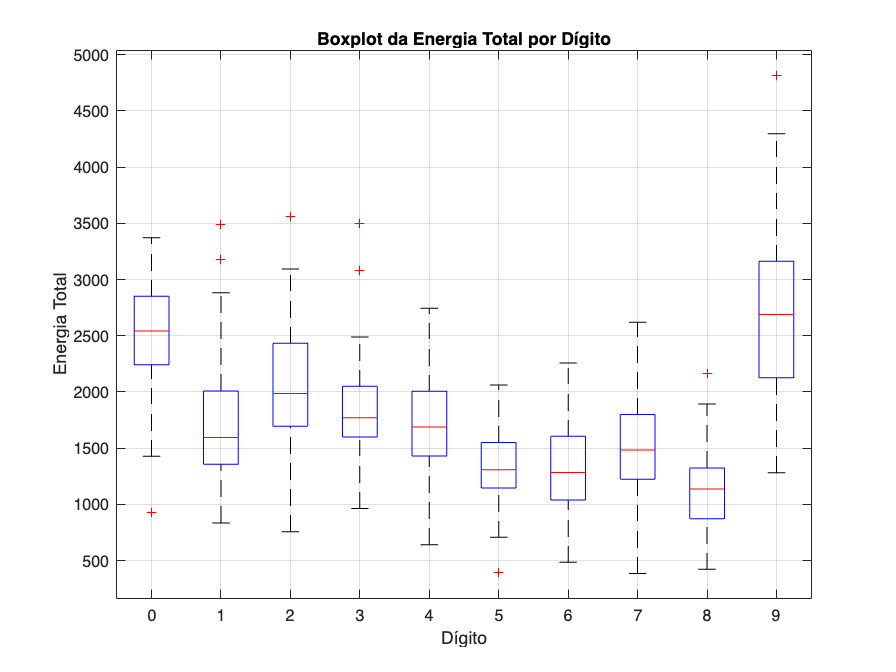

figure('Name','Boxplot - Total Energy por Dígito','NumberTitle','off');
boxplot(finalTable.TotalEnergy, finalTable.Digit);
xlabel('Dígito');
ylabel('Energia Total');
title('Boxplot da Energia Total por Dígito');
grid on

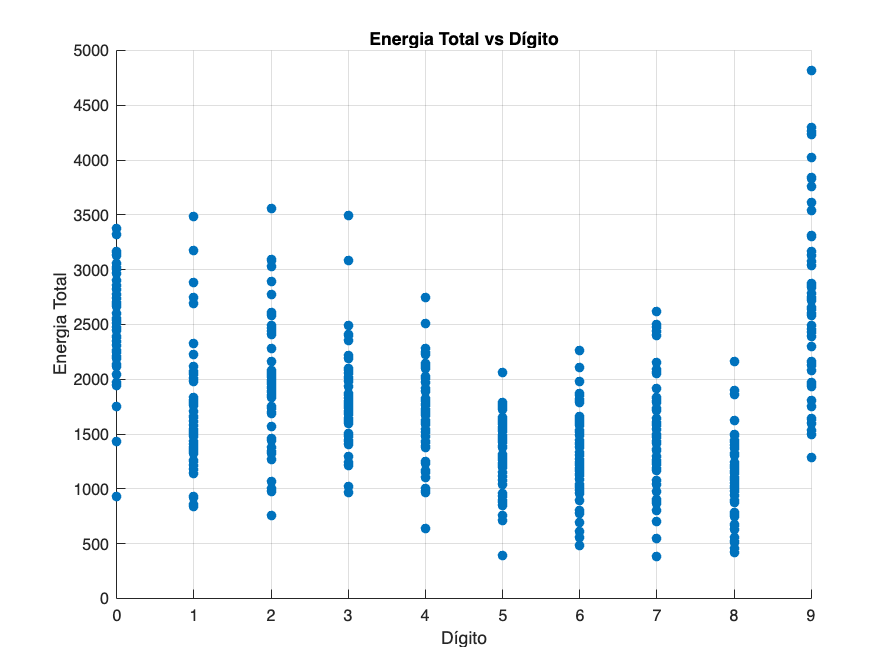

figure('Name','Scatter 2D - Energia Total vs Dígito','NumberTitle','off');
scatter(finalTable.Digit, finalTable.TotalEnergy, 'filled');
xlabel('Dígito');
ylabel('Energia Total');
title('Energia Total vs Dígito');
grid on

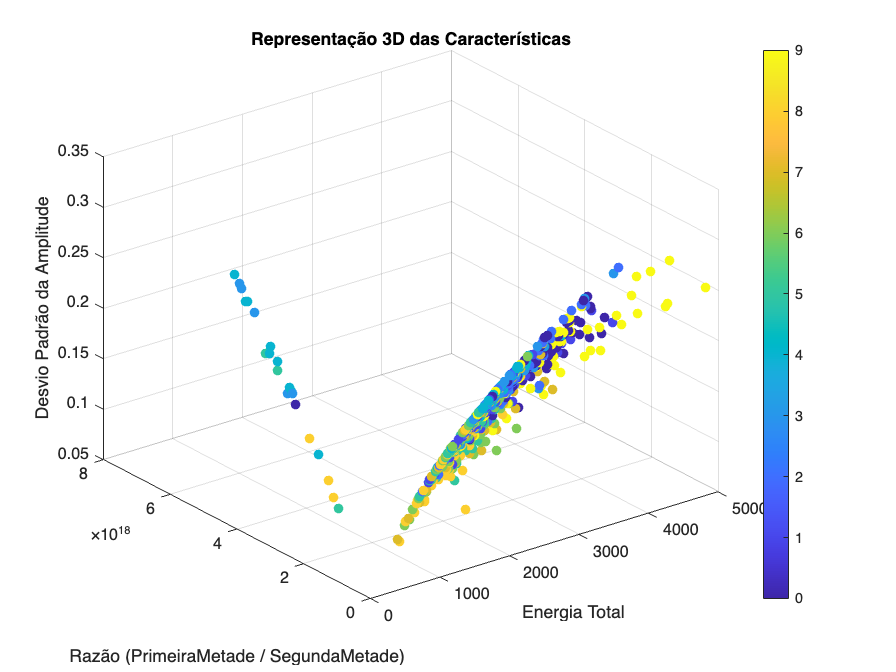

% Caso ainda não tenha a razão calculada, faça:
ratioEnergy = finalTable.EnergyFirstHalf ./ (finalTable.EnergySecondHalf + eps);
% (Usamos 'eps' para evitar divisão por zero caso a EnergySecondHalf seja 0.)

figure('Name','Scatter 3D - Três Características','NumberTitle','off');
scatter3(finalTable.TotalEnergy, ratioEnergy, finalTable.StdAmplitude, ...
    36, finalTable.Digit, 'filled'); 
% O 4º argumento (36) define o tamanho do marcador
% O 5º argumento (finalTable.Digit) define as cores de cada ponto baseadas no dígito

xlabel('Energia Total');
ylabel('Razão (PrimeiraMetade / SegundaMetade)');
zlabel('Desvio Padrão da Amplitude');
title('Representação 3D das Características');
grid on;
colorbar